% 聚类算法设计：基于k-means和轮廓系数自动确定最佳聚类数
% 数据来源：图片中的仿真结果坐标点
% 和初始数据有很大的关系！
clear; close all; clc;
%case2(1.281,-2.717)
%case2(3.440,0.008)
%case3(3.561,-0.120)
%case4(3.244,-1.069)
%case5(4.538,0.701)
%case6(4.176,0.487)
%case7(1.558,-2.488)
%case8(3.380,-0.751)
%case8(-1.489,-5.768)
%case9(3.305,-0.730)
%case10(2.976,-0.976)
% 定义数据点（从图片中提取的仿真结果坐标）


%近处(3.289,-0.667)
%(3.277,-0.776)
%(1.965,-1.827)
%(1.672,-2.367)

data = [
    1.281,-2.717;   % round1
    3.440,0.008;   % round2
    3.561,-0.120;   % round3
    3.244,-1.069;   % round4
    4.538,0.701;    % round5
    4.176,0.487 ;% round6
    1.558,-2.488; %round 7
    3.380,-0.751; %round 8
    3.305,-0.730; %round 9
    2.976,-0.976; % round 10;
    1.585,-2.341;
    2.948,-1.110;
];

% 数据标签（用于显示）
labels = {'round1', 'round2', 'round3', 'round4', 'round5', 'round6','round7','round8','round9','round10','11','12'};

% 由于数据点少，尝试k=2和k=3两种聚类方案
k_range = 2:3;
silhouette_scores = zeros(size(k_range));

fprintf('正在计算不同k值的聚类效果...\n');

正在计算不同k值的聚类效果...



% 计算每个k值的轮廓系数
for i = 1:length(k_range)
    k = k_range(i);
    idx = kmeans(data, k, 'Replicates', 10); % 重复10次以避免局部最优
    silhouette_vals = silhouette(data, idx);
    silhouette_scores(i) = mean(silhouette_vals);
    fprintf('k=%d 时，轮廓系数 = %.4f\n', k, silhouette_scores(i));
end

k=2 时，轮廓系数 = 0.8541
k=3 时，轮廓系数 = 0.7844



% 选择轮廓系数最大的k作为最佳聚类数
[best_score, best_idx] = max(silhouette_scores);
best_k = k_range(best_idx);
fprintf('\n最佳聚类数 k = %d (轮廓系数 = %.4f)\n', best_k, best_score);


最佳聚类数 k = 2 (轮廓系数 = 0.8541)


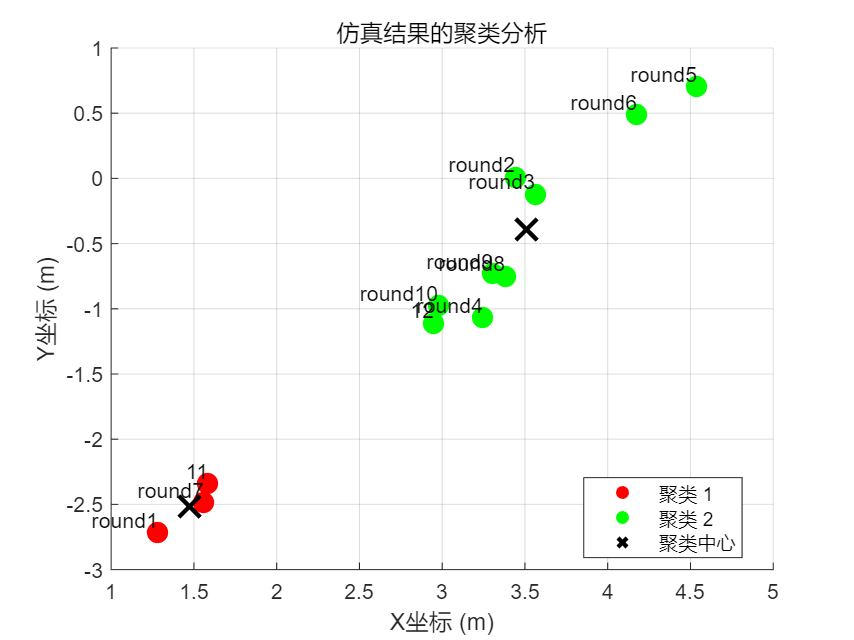


% 使用最佳k进行最终聚类
[idx, centers] = kmeans(data, best_k, 'Replicates', 10);

% 可视化聚类结果
figure;
hold on;
colors = ['r', 'g', 'b', 'c', 'm', 'y']; % 定义颜色数组

for i = 1:best_k
    cluster_points = data(idx == i, :);
    scatter(cluster_points(:,1), cluster_points(:,2), 100, colors(i), 'filled');
    
    % 标记每个点
    for j = 1:size(cluster_points, 1)
        point_idx = find(ismember(data, cluster_points(j,:), 'rows'));
        text(cluster_points(j,1), cluster_points(j,2), labels{point_idx}, ...
            'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
    end
end

% 绘制聚类中心
scatter(centers(:,1), centers(:,2), 200, 'k', 'x', 'LineWidth', 2);

title('仿真结果的聚类分析');
xlabel('X坐标 (m)');
ylabel('Y坐标 (m)');
legend_str = arrayfun(@(i) sprintf('聚类 %d', i), 1:best_k, 'UniformOutput', false);
legend_str{end+1} = '聚类中心';
legend(legend_str, 'Location', 'best');
grid on;
hold off;


% 输出聚类详情
fprintf('\n聚类结果详情：\n');


聚类结果详情：


for i = 1:best_k
    fprintf('聚类 %d 包含的点：\n', i);
    cluster_indices = find(idx == i);
    for j = 1:length(cluster_indices)
        point_idx = cluster_indices(j);
        fprintf('  %s: (%.3f, %.3f) m, 误差: %s\n', ...
                labels{point_idx}, ...
                data(point_idx,1), data(point_idx,2)); % 获取误差信息
    end
    fprintf('聚类中心: (%.3f, %.3f) m\n\n', centers(i,1), centers(i,2));
end

聚类 1 包含的点：


  round1: (1.281, -2.717) m, 误差:   round7: (1.558, -2.488) m, 误差:   11: (1.585, -2.341) m, 误差: 

聚类中心: (1.475, -2.515) m



聚类 2 包含的点：


  round2: (3.440, 0.008) m, 误差:   round3: (3.561, -0.120) m, 误差:   round4: (3.244, -1.069) m, 误差:   round5: (4.538, 0.701) m, 误差:   round6: (4.176, 0.487) m, 误差:   round8: (3.380, -0.751) m, 误差:   round9: (3.305, -0.730) m, 误差:   round10: (2.976, -0.976) m, 误差:   12: (2.948, -1.110) m, 误差: 

聚类中心: (3.508, -0.396) m




% 辅助函数：根据点索引返回误差字符串

function error_str = getErrorString(idx)
    % 从图片中提取的误差数据
    errors = {"0.292m", "0.381m", ">1m", ">1m", ">1m", ">1m"};
    error_str = errors{idx};
end